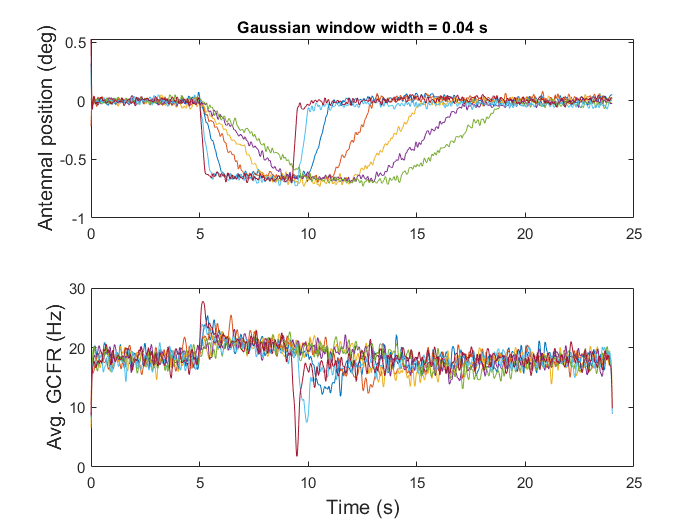

gauss_win_L = fs/4;

% gauss_win_alpha = 2;
sigma = 0.04; %logspace(-2,1,10);
%[0.01 0.03 0.05 0.08 0.1 0.5];


for i=1:length(sigma)
    gauss_win_alpha = (gauss_win_L-1)/(2*sigma(i)*fs);
    P = create_structs(rec_protocols_sorted,stim_protocols_hes_sorted,fs, stim_protocols_ifb_sorted, no_of_protocols, no_of_trials, single_trial_length, stim_order_sorted,max_chirp_frq, amp_sweep_frq, blwgn_fc, ON_dur, a, b, c, gauss_win_L, sigma(i), movementRadius);
    
    figure;
    
    for j=1:length(P)
        ax1 = subplot(2,1,1); plot(time(1:single_trial_length), -mean(P(j).antennal_movement, 1)); hold on;
        ylabel('Antennal position (deg)', 'FontSize',12);
        title(sprintf('Gaussian window width = %0.2f s', sigma(i)));
        
        ax2 = subplot(2,1,2); plot(time(1:single_trial_length), P(j).avg_gcfr); hold on;
        ylabel('Avg. GCFR (Hz)', 'FontSize',12);
        xlabel('Time (s)', 'FontSize',12);
        
        linkaxes([ax1 ax2], 'x');
    end
end

    
%{    
    max_FR = [];
    velocity = [];
    
    for k=1:length(P)
        stim_name = split(P(k).stim_name);
        delta_t = str2double(stim_name(2));
        pos_ref = mean(mean(P(k).antennal_movement(:,1:3*fs),2));
        pos_stim = mean(mean(P(k).antennal_movement(:, 8*fs:9*fs),2));
        amplitude = abs(pos_ref - pos_stim);
        velocity_values = repmat((amplitude/delta_t), [P(k).complete_trials,1]);
        velocity = [velocity; velocity_values];
        max_FR = [max_FR; max(P(k).gcfr, [], 2)];  
    end
    
    [velocity_sorted, idx] = sort(velocity, 'ascend');
    max_FR_sorted = max_FR(idx);
    meanMaxFR = median(reshape(max_FR_sorted, P(k).complete_trials, []),1);
    vel = unique(velocity_sorted);
    % velocity_sorted = num2str(velocity_sorted, '%.3f');
    subplot(2,2,[2,4]);
    boxchart(velocity_sorted, max_FR_sorted, 'BoxWidth', 0.03, 'MarkerStyle',"+"); hold on;
    plot(vel, meanMaxFR, '-o');  hold off;
    % boxplot(max_FR_sorted, velocity_sorted);
    % ylim([0 100]);
    ylabel('Firing rate (Hz)', "FontSize", 12);
    xlabel('Angular velocity (deg/s)', "FontSize", 12);
%     title(sprintf('Gaussian window length = %0.2f s', gauss_win_L(i)/fs));
    
    FR =reshape(max_FR_sorted, P(k).complete_trials, []);
    p = ranksum(FR(:,1), FR(:,end))
end
%}


